clear

addpath("functions\")

#### Add defect to pipe

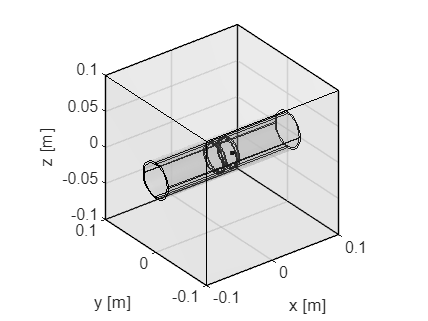

Model = myModel;
freqs = [1000]; % (Hz)
mesh_size = 4; % 1:finest 9:coarsest

Model = ComsolInterface('Build', Model);

ComsolInterface('AddCircularDefect',    Model, deg2rad(30), 0e-3, 0.004,         21e-3, 26e-3)
% ComsolInterface('AddRectangularDefect', Model, deg2rad(10), -5e-3, 0.009, 0.002,  21e-3, 24e-3)

figure
ComsolInterface('PlotGeometry', Model)

#### Compute fields

shift = 0;
ComsolInterface('Solve', Model, freqs(1), mesh_size, shift)

rho = 23.75e-3;
phi = linspace(0, pi/2, 31);
z = linspace(-pi/4, pi/4, 31) * rho;

[phi,z,rho] = ndgrid(phi,z,rho);

[Ephi,Ez] = ComsolInterface('EvaluateField', Model, {'Jphi' 'Jz'}, rho,phi,z);


figure
quiver(phi.*rho, z, Ephi, Ez)

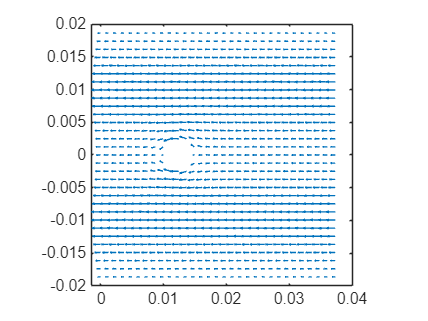

axis square